L'immagine mosaic.jpg è composta dal mosaico di due diverse texture, secondo la geometria mostrata in ground truth.jpg. Per segmentare l'immagine, si estrae un vettore di due feature 

per ogni pixel e poi si applica il clustering k-means di tali vettori.

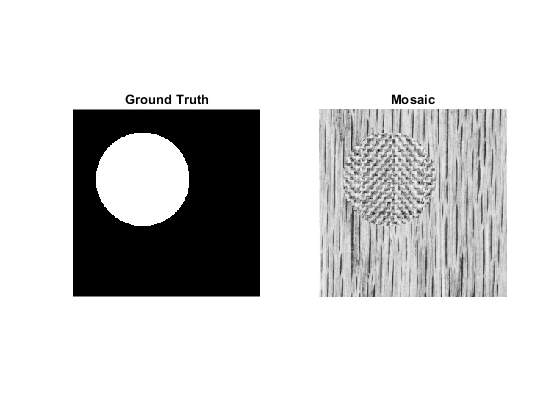

close all; clear all; clc;
gt = double(imread('ground_truth.jpg'));
mos = double(imread('mosaic.jpg'));

% Vettore di feature
F = nlfilter(mos,[3 3],@elabora);

% Clustering
med = imfilter(F,fspecial('gaussian',9,3));
[idx,centroidi] = exKmeans(med(:),2);
[~,label] = sort(centroidi);
mask = zeros(size(F));
mask(idx==label(1)) = 1;

% Erosione
se = strel('disk',3);
mask2 = imerode(mask,se);
mask3 = 1-mask2;
se = strel('disk',12,8);
mask4 = imerode(mask3,se);

% Visualizzazione
figure;
subplot(121); imshow(gt,[]); title('Ground Truth');
subplot(122); imshow(mos,[]); title('Mosaic');

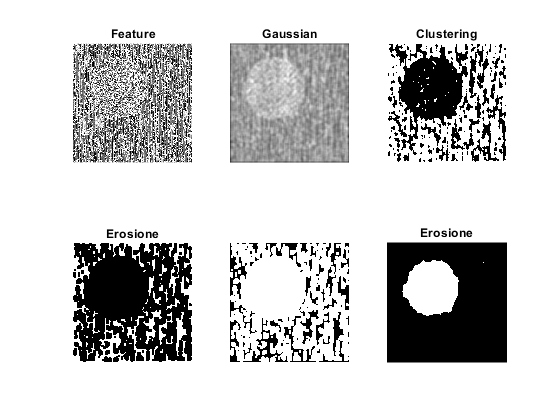

figure;
subplot(231); imshow(F,[]); title('Feature');
subplot(232); imshow(med,[]); title('Gaussian');
subplot(233); imshow(mask,[]); title('Clustering');
subplot(234); imshow(mask2,[]); title('Erosione');
subplot(235); imshow(mask3,[]); 
subplot(236); imshow(mask4); title('Erosione');

function F = elabora(x)

    X0 = x(2,2);
    X(1) = x(1,1);  X(2) = x(1,2);
    X(3) = x(1,3);  X(4) = x(2,3);
    X(5) = x(3,3);  X(6) = x(3,2);
    X(7) = x(3,1);  X(8) = x(2,1);

    for i=1:8
       if (X0>X(i))
           b(i) = 1;
       else 
           b(i) = 0;
       end
    end

    % Numero di 1 nel vettore b
    S = sum(b);
    D = 0;
    for i=1:7
        % Numero di transizioni nel vettore b
        D = D + abs(b(i)-b(i+1)) + abs(b(8)-b(1));
    end

    if (D<=2) F = S; else F = 9; end
end